# LQR Control of an Inverted Pendulum (Live Script)

This live script demonstrates the design and simulation of an LQR controller for an inverted pendulum model, including delay compensation via a Smith Predictor and realistic muscle dynamics.

## 1. Initialize Workspace

clear
clc
close all

## 2. Physical Parameters

Define the biomechanical parameters of the pendulum (human body segment).

g = 9.81;          % Gravity constant (m/s^2)
m = 74;            % Pendulum mass (kg)
c = 5.73;          % Viscous damping coefficient (N.m.s/rad)
L = 1.7 * 0.52;   % Pendulum length (m)
I = 0.971 * m * L^2;  % Moment of inertia (kg.m^2)

fprintf('Pendulum length L = %.4f m\n', L)

Pendulum length L = 0.8840 m


fprintf('Moment of inertia I = %.4f kg.m^2\n', I)

Moment of inertia I = 56.1507 kg.m^2


## 3. State-Space Model

The linearised inverted pendulum dynamics are represented in state-space form. States: x = [theta; theta_dot] (angle and angular velocity) The "G" suffix denotes the model used for Pade-delayed LQR design. The difference is 0.3 multiplication to not include passsive stiffness

% Model with 0.3 gravity factor (used for controller design with delay)
AG = [0, 1; 0.3*m*g*L/I, -c/I];
BG = [0; 1/I];
CG = eye(2);
DG = 0;

% Nominal model (used for simulation and CARE)
A = [0, 1; m*g*L/I, -c/I];
B = [0; 1/I];
C = eye(2);
D = 0;

disp('Nominal A matrix:'), disp(A)

Nominal A matrix:
         0    1.0000
   11.4287   -0.1020



disp('Nominal B matrix:'), disp(B)

Nominal B matrix:
         0
    0.0178



## 4. Timing & Simulation Parameters

T_d_input  = 0.06;   % Sensory (input) delay (s)
T_d_output = 0.06;   % Motor (output) delay (s)
T_r_delay  = 0;      % Robotic/additional delay (s)
% T_r_delay  = 0.250;      % Robotic/additional delay (s)

dt = 0.004;          % Time step (s)
T  = 60;             % Total simulation time (s)
N  = T / dt;         % Number of time steps

Fs = 250;            % Sampling rate (Hz)
Ns = T * Fs;         % Number of samples
f  = Fs * (0:(Ns/2)) / Ns;  % Frequency axis

fprintf('Simulation: %.0f s at dt=%.4f s  (%d steps)\n', T, dt, N)

Simulation: 60 s at dt=0.0040 s  (15000 steps)


## 5. Noise Parameters

Motor and sensory noise coefficients applied during simulation.

mn_coeff_base  = 1;
mn_coeff       = mn_coeff_base;
thn_coeff      = 0.002;
thdotn_coeff   = 0.0036;

disp('Noise coefficients are set.')

Noise coefficients are set.


## 6. Load Pre-Recorded Noise Data

Noise signals recorded from experimental data are loaded here.

motor_noiseTest  = readmatrix("NoiseP1.txt");
th_noiseTest     = readmatrix("NoiseP2.txt");
thdot_noiseTest  = readmatrix("NoiseP3.txt");

disp('Noise files loaded successfully.')

Noise files loaded successfully.


## 7. LQR Weight Matrices (Single Q)

Choose a single set of LQR weighting matrices Q and R. Q penalises state deviation; R penalises control effort.

Q_val = 1;       % State weight (scalar, applied as Q = Q_val * I)
R_val = 10^-1.5;    % Control weight

Q = eye(2) .* Q_val;
R = R_val;

fprintf('Q = %.4g * I,  R = %.4g\n', Q_val, R_val)

Q = 1 * I,  R = 0.03162


## 8. Delay-Augmented System & Padé Approximation

The sensory and motor delays are approximated using a 2nd-order Padé expansion, allowing standard LQR design on the augmented state-space.

Gain_delay = 0;   % Additional gain path delay (s)
sys_delayed = ss(AG, BG, CG, DG, ...
    'InputDelay',  T_d_input + Gain_delay, ...
    'OutputDelay', T_d_output);

order = 2;
sys_delayed_approx = pade(sys_delayed, order);
[A_d, B_d, ~, ~] = ssdata(sys_delayed_approx);

disp('Padé-approximated system obtained.')

Padé-approximated system obtained.


fprintf('Augmented state dimension: %d\n', size(A_d,1))

Augmented state dimension: 8


## 9. LQR Gain Computation

Two gain computations are shown: (a) K2 via CARE on the nominal model. (b) K via lqr() on the Padé-augmented model (used in simulation).

Q_d = eye(size(A_d)) .* Q_val;

% (a) CARE on nominal model
[P, ~, ~] = care(A, B, Q, R);
K2 = R \ (B' * P);
fprintf('CARE gain K2 = [%.4f, %.4f]\n', K2(1), K2(2))

CARE gain K2 = [1283.4866, 374.0092]



% (b) LQR on delayed (Padé) model — extract gains for original states
K_full = lqr(A_d, B_d, Q_d, R);
K = K_full(5:6);   % Gains corresponding to [theta, theta_dot]
fprintf('LQR gain K  = [%.4f, %.4f]\n', K(1), K(2))

LQR gain K  = [846.6452, 444.8391]


## 10. Smith Predictor Forward Simulation — Single Trial

Run one representative trial (iTest = 1) to illustrate the closed-loop behaviour with Smith Predictor, muscle dynamics, and passive torque.

alpha = 0;
beta  = 0;
% beta  = 0.2;
train_delay = 0;
% train_delay = 0.25;

T_d_forward = T_d_output + T_d_input + train_delay;
% nForward    = 1;   % Steps used in Smith Predictor forward pass
nForward = (round(T_d_forward/dt));

% Initialise state
init_angle_rad = 0 * pi / 180;
state     = [init_angle_rad; 0];   % [theta; theta_dot]
u         = zeros(1, N);
finaltorque = zeros(1, N);
acc_temp  = zeros(1, N);
state_hat_history = zeros(2, N);

prevReversal        = 0;
prevPStorque        = 0;
prevPStorqueHistory = 0;
prev_state          = state;
prev_act_u          = 0;

iTest = 1;   % Single trial index for noise lookup

for k = 1:N

    % --- Smith Predictor initialisation ---
    state_hat       = zeros(2, round(T_d_input/dt) + round(T_d_output/dt) + round(T_r_delay/dt));
    u_hat           = zeros(1, size(state_hat, 2));
    state_hat(:, 1) = state(:, k);

    % Add sensory noise
    state_hat(1, 1) = state_hat(1, 1) + thn_coeff    * th_noiseTest(k, iTest);
    state_hat(2, 1) = state_hat(2, 1) + thdotn_coeff * thdot_noiseTest(k, iTest);

    state_hat_error       = zeros(2, size(state_hat, 2));
    state_hat_error(1, 1) = thn_coeff;
    state_hat_error(2, 1) = thdotn_coeff;

    now_state = state(:, k);

    if k > (round(T_d_input/dt) + round(T_d_output/dt) + round(T_r_delay/dt)) && k < N
        error_prediction = state_hat(:, 1) - state_hat_history(:, k+1);
    else
        error_prediction = 0;
    end

    % --- Forward simulation loop (Smith Predictor) ---
    for iForward = 1:nForward
        if (k + iForward - 2) >= (round(T_d_input/dt) + round(T_d_output/dt) + round(T_r_delay/dt))
            u_hat(iForward)       = -K * state_hat(:, iForward);
            u_hat_error(iForward) = abs(u_hat(iForward)) * mn_coeff;
        else
            u_hat(iForward)       = 0;
            u_hat_error(iForward) = 0;
        end

        state_hat_dot            = A * state_hat(:, iForward) + B * u_hat(iForward);
        state_hat(:, iForward+1) = state_hat(:, iForward) + state_hat_dot * dt;

        state_hat_dot_error            = A * state_hat_error(:, iForward) + B * u_hat_error(iForward);
        state_hat_error(:, iForward+1) = state_hat_error(:, iForward) + state_hat_dot_error * dt;
    end

    % --- Worst-case correction ---
    correction_state_hat = [ sign(state_hat(1, iForward)) * thn_coeff    * alpha;
                              sign(state_hat(2, iForward)) * thdotn_coeff * alpha ];
    correction_state_hat = correction_state_hat + error_prediction * beta;
    correction_u_hat     = -K * correction_state_hat;

    % --- Apply control ---
    delay_steps = round(T_d_input/dt) + round(T_d_output/dt) + round(T_r_delay/dt);
    if k <= (N - delay_steps)
        u(k + delay_steps - 1)              = u_hat(iForward) + correction_u_hat;
        state_hat_history(:, k + delay_steps) = state_hat(:, iForward);
    end

    torque_final = u(k);

    % --- Muscle dynamics ---
    [torque_final, prev_act_u] = muscle_dyn(prev_act_u, torque_final, dt);

    % --- Passive torque ---
    [psTorque, prevReversal, prevPStorque, prevPStorqueHistory] = ...
        passive_torque(now_state, prev_state, prevReversal, ...
        prevPStorque, prevPStorqueHistory, m, g, L);

    prev_state = now_state;

    % --- Torque saturation (physiological limits) ---
    torque_final = max(min(torque_final, 84), -256);

    finaltorque(k) = torque_final * (1 + custom_TN(torque_final) * mn_coeff * motor_noiseTest(k, iTest)) - psTorque;

    % --- Pendulum dynamics ---
    state_dot       = A * state(:, k) + B * finaltorque(k);
    state(:, k+1)   = state(:, k) + state_dot * dt;
    acc_temp(k)     = state_dot(2);

end

disp('Simulation complete.')

Simulation complete.


## 11. Results — Pendulum Angle & Control Torque

Plot the pendulum angle and control input over the full simulation.

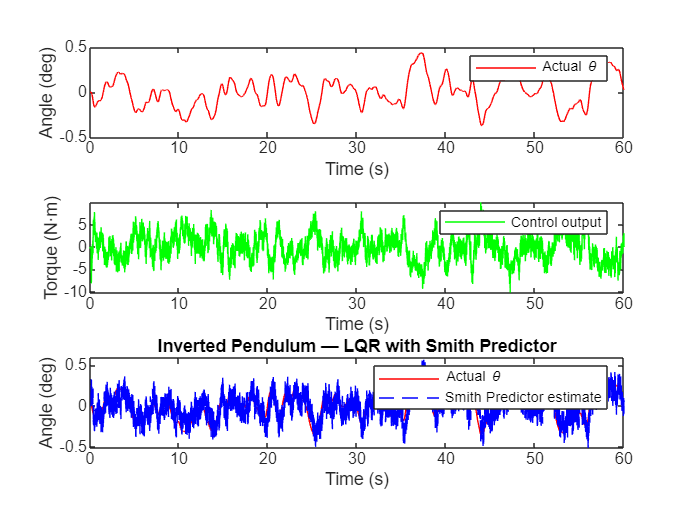

time = dt:dt:N*dt;
close all
figure;
subplot(3,1,1)
plot(time, state(1, 1:N)*180/pi, 'r')
xlabel('Time (s)'); ylabel('Angle (deg)')
legend('Actual \theta')
xlim([0 T])

subplot(3,1,2)
plot(time, finaltorque(1:N), 'g')
xlabel('Time (s)'); ylabel('Torque (N·m)')
legend('Control output')

subplot(3,1,3)
plot(time, state(1, 1:N)*180/pi, 'r', ...
     dt:dt:N*dt, state_hat_history(1, 1:N)*180/pi, 'b--')
legend('Actual \theta', 'Smith Predictor estimate')
xlabel('Time (s)'); ylabel('Angle (deg)')
title('Inverted Pendulum — LQR with Smith Predictor')
xlim([0 T])

## ---- Helper Functions ----

function [torque_final, prev_act] = muscle_dyn(prevAct, true_torque, dt)
% MUSCLE_DYN  First-order muscle activation dynamics.
    if sign(true_torque) == -1
        MVC = 256;
    else
        MVC = 84;
    end
    activation = true_torque / MVC;
    if sign(true_torque) ~= sign(prevAct)
        prevAct = 0;
    end
    if abs(activation) >= abs(prevAct)
        tau = 0.01 * (0.5 + 1.5 * abs(prevAct));
    else
        tau = 0.04 / (0.5 + 1.5 * abs(prevAct));
    end
    output = (abs(activation) - abs(prevAct)) / tau * dt + abs(prevAct);
    torque_final = sign(true_torque) * output * MVC;
    prev_act = activation;
end

function [psTorque, prevReversal, prevPStorque, prevPStorqueHistory] = ...
    passive_torque(now_state, prev_state, prevReversal, ...
    prevPStorque, prevPStorqueHistory, m, g, L)
% PASSIVE_TORQUE  Passive ankle stiffness torque (Loram et al.).
    th      = now_state(1);
    thdot   = now_state(2);
    prevThDot = prev_state(2);
    prevVelocitySign = sign(prevThDot);
    if prevVelocitySign == 0, prevVelocitySign = 1; end
    rotationSign = sign(thdot);
    if rotationSign == 0, rotationSign = 1; end
    if rotationSign ~= prevVelocitySign
        prevReversal = th;
        prevPStorque = prevPStorqueHistory;
    end
    if abs(th - prevReversal) <= 0.03/180*pi
        rotation = rotationSign * 0.03/180*pi;
    else
        rotation = th - prevReversal;
    end
    coeffT = 0.467 * abs(rotation)^(-0.334) * m * 180/pi * 2 * g * L / (11*180/pi);
    psTorque = coeffT * rotation + prevPStorque;
    prevPStorqueHistory = psTorque;
end

function TNoise = custom_TN(TorqueInput)
% CUSTOM_TN  Signal-dependent motor noise coefficient.
    if TorqueInput < 0
        sgn = -1;
    else
        sgn = 1;
    end
    if sgn == -1
        MVC = TorqueInput / 256;
        if MVC < 10
            TNoise = 0.021*MVC + 0.121;
        else
            TNoise = 0.042*MVC - 0.109;
        end
    else
        MVC = TorqueInput / 84;
        if MVC < 30
            TNoise = 0.013*MVC + 0.058;
        else
            TNoise = 0.021*MVC - 0.182;
        end
    end
end